%--------------------------
clear all;
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

MatNames = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames1 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames3 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
HDRlNames2 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};

% load data
load(strcat(Datapath,'Exp1Mi_data.mat'));
load(strcat(Datapath,'Exp2Mi_data.mat'));
load(strcat(Datapath,'Exp1Th_data.mat'));
load(strcat(Datapath,'Exp2Th_data.mat'));
load(strcat(Datapath,'Exp3_data.mat'));
load(strcat(Datapath,'Inoue_data.mat'));

%変数
Exp3HMSPT = Exp3RowHMSPT;
Exp3HMS = Exp3ZsHMS;
Exp3HS = Exp3ZsHS;
Exp3HM = Exp3ZsHM;
Exp3H = Exp3ZsH;
Exp3HM15 = Exp3Zs15bnyHM;
Exp3H15 = Exp3Zs15bnyH;
err_Exp3HMS = error_Exp3ZsHMS;
err_Exp3HM = error_Exp3ZsHM;
err_Exp3HS = error_Exp3ZsHS;
err_Exp3H = error_Exp3ZsH;
err_Exp3HM15 = error_Exp3HM15;
err_Exp3H15 = error_Exp3H15;

%{
InoueHMS = InoueNormHMS;
InoueHM = InoueNormHM;
InoueHS = InoueNormHS;
InoueH = InoueNormH;
InoueHM15 = InoueNormHM15;
InoueH15 = InoueNormH15;
%}
InoueHMS = InoueZsHMS;
InoueHM = InoueZsHM;
InoueHS = InoueZsHS;
InoueH = InoueZsH;
InoueHM15 = InoueZs15bnyHM;
InoueH15 = InoueZs15bnyH;

Exp2MiHM15 = Exp2MiZsHM15;
Exp2MiH15 = Exp2MiZsH15;
err_Exp2MiHM15 = error_Exp2MiZsHM15;
err_Exp2MiH15 = error_Exp2MiZsH15;
Exp2ThHM15 = Exp2ThZsHM15;
Exp2ThH15 = Exp2ThZsH15;
err_Exp2ThHM15 = error_Exp2ThZsHM15;
err_Exp2ThH15 = error_Exp2ThZsH15;

Exp1MiHM15 = Exp1MiNormHM15;
Exp1MiH15 = Exp1MiNormH15;
err_Exp1MiHM15 = error_Exp1MiNormHM15;
err_Exp1MiH15 = error_Exp1ThNormH15;
Exp1ThHM15 = Exp1ThNormHM15;
Exp1ThH15 = Exp1ThNormH15;
err_Exp1ThHM15 = error_Exp1ThNormHM15;
err_Exp1ThH15 = error_Exp1ThNormH15;


%---------------------------------------
% Exp3 光沢感応答
%---------------------------------------
Exp3RowHMSPT_per = permute(Exp3HMSPT,[2,3,1,4,5]);
Exp3RowHMSPT_reshape = reshape(Exp3RowHMSPT_per,size(Exp3RowHMSPT_per,1),size(Exp3RowHMSPT_per,2),[]);

%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        values = Exp3RowHMSPT_reshape(mat,shape,:);

        histogram(values,'BinEdges',0:0.025:1);
        xlabel('Bin','FontSize',14); 
        ylabel('Frequency','FontSize',14);
        title(sprintf('%s',string(ShapeNames(shape))),'FontSize',19);
        grid on;
    end
    plotname = sprintf('%s/Exp3_bin_%s_Hist.jpg',ana_result,string(MatNames2(mat)));
    saveas(gcf, plotname);
end

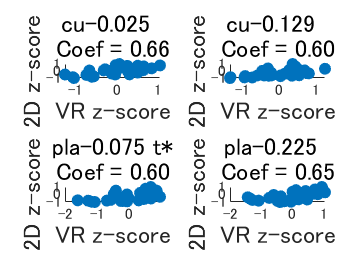

%-----------------------------------
% Exp3 vs Old HDR,Material coef
%-----------------------------------
% tp-value (0.05以下で母集団の平均値に有意差あり)
M_T_p_value = zeros(1,4);
for shape = 1:4
    [~,M_T_p_value(shape)] = ttest(Exp3HS(:,shape),InoueHS(:,shape));
end
HM_T_p_value = zeros(size(Exp3HS));
for hdr = size(HM_T_p_value,1)
    for shape = size(HM_T_p_value,2)
        [~,HM_T_p_value(hdr,shape)] = ttest(Exp3HMS(hdr,:,shape),InoueHMS(hdr,:,shape));
    end
end
% fp-value (0.05以下で母集団の分散値に有意差あり)
M_F_p_value = zeros(1,4);
for shape = 1:4
    [~,M_F_p_value(shape),~,~] = vartest2(Exp3HS(:,shape),InoueHS(:,shape));
end
HM_F_p_value = zeros(size(Exp3HS));
for hdr = size(HM_F_p_value,1)
    for shape = size(HM_F_p_value,2)
        [~,HM_F_p_value(hdr,shape)] = vartest2(Exp3HMS(hdr,:,shape),InoueHMS(hdr,:,shape));
    end
end

coef_list = [];
slop_list = [];
amp = 1.0;

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    x = Exp3HM(:,mat);
    y = InoueHM(:,mat);
    r = corrcoef(x,y);
    r_value = r(1,2);
    coef_list(end+1) = r_value;
    p = polyfit(x,y,1);
    p_fit = polyval(p,x);
    slop_list(end+1) = p(1);

    scatter(x,y,'filled');
    hold on;
    %plot(x,p_fit,'r-','LineWidth',1.5);
    hold off;

    xlabel('VR z-score','FontSize',12*amp);
    ylabel('2D z-score','FontSize',12*amp);
    if M_T_p_value(mat) < 0.05
        graphtextT = sprintf('t*');
    else 
        graphtextT = sprintf(' ');
    end
    if M_F_p_value(mat) < 0.05
        graphtextF = sprintf('f*');
    else 
        graphtextF = sprintf(' ');
    end
    %title(sprintf('%s: Coef = %.2f,Slope = %.2f', string(MatNames2(mat)),coef_list(mat),slop_list(mat)),'FontSize',12*amp);
    title(sprintf('%s %s\nCoef = %.2f', string(MatNames2(mat)),graphtextT,coef_list(mat)),'FontSize',12*amp);
end
plotname = strcat(ana_result, '/Exp3vsOld_Mat_Coef.jpg');
saveas(gcf, plotname);


%{
%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    bar1 = Exp3HM(:,mat);
    err1 = err_Exp3HM(:,mat);
    bar2 = InoueHM(:,mat);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    hold on;
    bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
    bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
    %errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
    hold off;

    ylim([-1.2 1.2]);
    set(gca, 'XTick', x);
    xticklabels(HDRNames3);
    xtickangle(90);
    set(gca,'FontSize',6*amp);

    xlabel('HDR','FontSize',12*amp); 
    ylabel('Normalized z-score','FontSize',12*amp);
    title(sprintf('%s: Coef = %.2f,Slope = %.2f', string(MatNames2(mat)),coef_list(mat),slop_list(mat)),'FontSize',12*amp);
    legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
    legend('boxoff');
    grid on;
end
plotname = strcat(ana_result, '/Exp3vsOld_Mat_Hist.jpg');
saveas(gcf, plotname);
%}

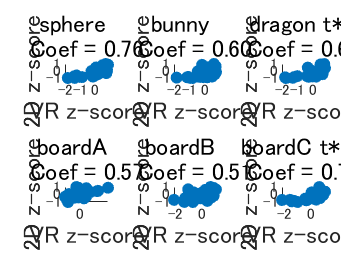

%-----------------------------------
% Exp3 vs Old HDR,Shape 
%-----------------------------------
% tp-value (0.05以下で母集団の平均値に有意差あり)
S_T_p_value = zeros(1,6);
for shape = 1:6
    [~,S_T_p_value(shape)] = ttest(Exp3HS(:,shape),InoueHS(:,shape));
end
HS_T_p_value = zeros(size(Exp3HS));
for hdr = size(HS_T_p_value,1)
    for shape = size(HS_T_p_value,2)
        [~,HS_T_p_value(hdr,shape)] = ttest(Exp3HMS(hdr,:,shape),InoueHMS(hdr,:,shape));
    end
end
% fp-value (0.05以下で母集団の分散値に有意差あり)
S_F_p_value = zeros(1,6);
for shape = 1:6
    [~,S_F_p_value(shape),~,~] = vartest2(Exp3HS(:,shape),InoueHS(:,shape));
end
HS_F_p_value = zeros(size(Exp3HS));
for hdr = size(HS_F_p_value,1)
    for shape = size(HS_F_p_value,2)
        [~,HS_F_p_value(hdr,shape)] = vartest2(Exp3HMS(hdr,:,shape),InoueHMS(hdr,:,shape));
    end
end

coef_list = [];
slop_list = [];
amp = 1.0;

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    x = Exp3HS(:,shape);
    y = InoueHS(:,shape);
    r = corrcoef(x,y);
    r_value = r(1,2);
    coef_list(end+1) = r_value;
    p = polyfit(x,y,1);
    p_fit = polyval(p,x);
    slop_list(end+1) = p(1);

    scatter(x,y,'filled');
    hold on;
    %plot(x,p_fit,'r-','LineWidth',1.5);
    hold off;

    xlabel('VR z-score','FontSize',12*amp);
    ylabel('2D z-score','FontSize',12*amp);
    if S_T_p_value(shape) < 0.05
        graphtextT = sprintf('t*');
    else 
        graphtextT = sprintf(' ');
    end
    if S_F_p_value(shape) < 0.05
        graphtextF = sprintf('f*');
    else 
        graphtextF = sprintf(' ');
    end
    %title(sprintf('%s\nCoef = %.2f,Slope = %.2f', string(ShapeNames(shape)),coef_list(shape),slop_list(shape)),'FontSize',12*amp);
    title(sprintf('%s %s\nCoef = %.2f', string(ShapeNames(shape)),graphtextT,coef_list(shape)),'FontSize',12*amp);
end
plotname = strcat(ana_result, '/Exp3vsOld_Shape_Coef.jpg');
saveas(gcf, plotname);


%{
% coef hisgram
figure;
hold on;
x = 1:length(coef_list);
bar_width = 0.4;
bar_coef = bar(x,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_coef = bar(x - bar_width/2,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_slope = bar(x + bar_width/2,slop_list,bar_width, 'FaceColor', 'r', 'DisplayName', 'Slope');
for i = 1:length(coef_list)
    graphtext1 = sprintf('%.2f',coef_list(i));
    text(i - bar_width/2,coef_list(i),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    %graphtext2 = sprintf('%.2f',slop_list(i));
    %text(i + bar_width/2,slop_list(i),graphtext2,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    if S_p_value(i) < 0.05
        graphtext3 = sprintf('*');
        text(i,max(coef_list(i),slop_list(i))+0.05,graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    end
end
ylim([0 1.0]);
set(gca, 'XTick', x);
xticklabels(ShapeNames);
set(gca,'FontSize',12*amp);
xlabel('Shape types','FontSize',18*amp);
ylabel('Value','FontSize',18*amp);
title(sprintf('VR VS 2D Coef about Shape'),'FontSize',18*amp);
%legend([bar_coef, bar_slope], {'Coef', 'Slope'}, 'Location', 'best','Orientation','vertical');
legend(bar_coef, 'Coef', 'Location', 'best','Orientation','vertical');
text(0,0.95, '* : p-value < 0.05', 'FontSize', 15*amp);
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_Shape_Coefbar.jpg');
saveas(gcf, plotname);
%}

%{
%histgram2
figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    bar1 = Exp3HS(:,shape);
    err1 = err_Exp3HS(:,shape);
    bar2 = InoueHS(:,shape);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    hold on;
    bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
    bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
    %errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
    hold off;

    ylim([-1.2 1.2]);
    set(gca, 'XTick', x);
    xticklabels(HDRNames3);
    xtickangle(90);
    set(gca,'FontSize',6*amp);

    xlabel('HDR','FontSize',12*amp); 
    ylabel('Normalized z-score','FontSize',12*amp);
    title(sprintf('%s\nCoef = %.2f,Slope = %.2f', string(ShapeNames(shape)),coef_list(shape),slop_list(shape)),'FontSize',12*amp);
    legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
    legend('boxoff');
    grid on;
end
plotname = strcat(ana_result, '/Exp3vsOld_Shape_Hist.jpg');
saveas(gcf, plotname);
%}

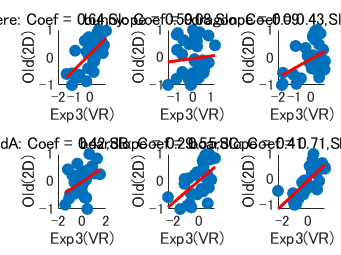

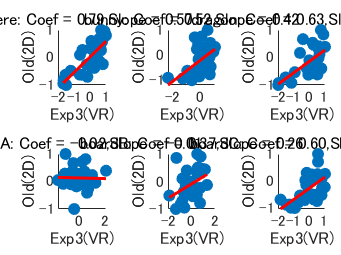

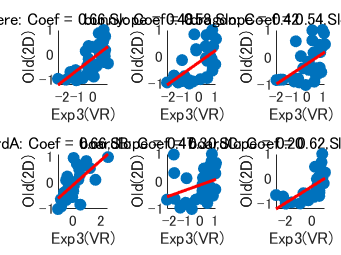

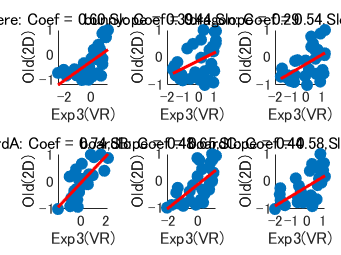

%-----------------------------------
% Exp3 vs Old HDR,Material,Shape coef
%-----------------------------------
coef_list = zeros(size(Exp3HMS,2),size(Exp3HMS,3));
slop_list = zeros(size(Exp3HMS,2),size(Exp3HMS,3));
amp = 1;

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        x = Exp3HMS(:,mat,shape);
        y = InoueHMS(:,mat,shape);
        r = corrcoef(x,y);
        r_value = r(1,2);
        coef_list(mat,shape) = r_value;
        p = polyfit(x,y,1);
        p_fit = polyval(p,x);
        slop_list(mat,shape) = p(1);
    
        scatter(x,y,'filled');
        hold on;
        plot(x,p_fit,'r-','LineWidth',1.5);
        hold off;
    
        xlabel('Exp3(VR)','FontSize',12*amp);
        ylabel('Old(2D)','FontSize',12*amp);
        title(sprintf('%s: Coef = %.2f,Slope = %.2f',string(ShapeNames(shape)),coef_list(mat,shape),slop_list(mat,shape)),'FontSize',12*amp);
    end
    plotname = sprintf('%s/Exp3vsOld_MS_%s_Coef.jpg',ana_result,string(MatNames2(mat)));
    saveas(gcf, plotname);
end

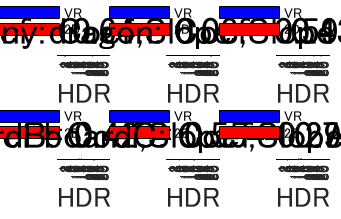

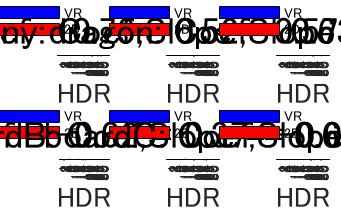

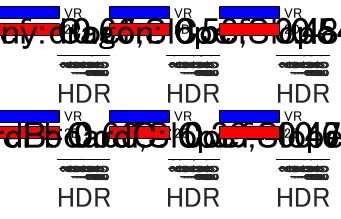

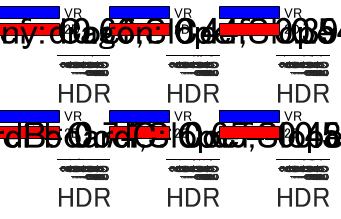


%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        bar1 = Exp3HMS(:,mat,shape);
        err1 = err_Exp3HMS(:,mat,shape);
        bar2 = InoueHMS(:,mat,shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        hold on;
        bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
        bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
        %errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
        hold off;
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', x);
        xticklabels(HDRNames3);
        xtickangle(90);
        set(gca,'FontSize',6*amp);
    
        xlabel('HDR','FontSize',12*amp); 
        ylabel('Normalized z-score','FontSize',12*amp);
        title(sprintf('%s: Coef = %.2f,Slope = %.2f',string(ShapeNames(shape)),coef_list(mat,shape),slop_list(mat,shape)),'FontSize',12*amp);
        legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
        legend('boxoff');
        grid on;
    end
    plotname = sprintf('%s/Exp3vsOld_MS_%s_Hist.jpg',ana_result,string(MatNames2(mat)));
    saveas(gcf, plotname);
end

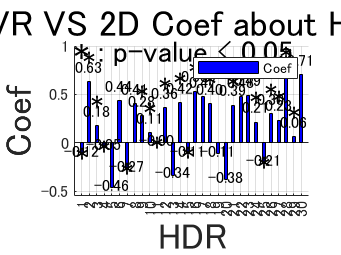

%-----------------------------------
% Exp3 vs Old HDR coef
%-----------------------------------
Exp3HMS_reshaped = reshape(Exp3HMS,size(Exp3HMS,1),[]);
InoueHMS_reshaped = reshape(InoueHMS,size(InoueHMS,1),[]);
% tp-value (0.05以下で母集団の平均値に有意差あり)
H_T_p_value = zeros(1,30);
for hdr = 1:size(Exp3H)
    [~,H_T_p_value(hdr)] = ttest(Exp3HMS_reshaped(hdr,:),InoueHMS_reshaped(hdr,:));
end

% fp-value (0.05以下で母集団の分散値に有意差あり)
H_F_p_value = zeros(1,30);
for hdr = 1:size(Exp3H)
    [~,H_F_p_value(hdr),~,~] = vartest2(Exp3HMS_reshaped(hdr,:),InoueHMS_reshaped(hdr,:));
end

coef_list = zeros(size(Exp3H));
slop_list = zeros(size(Exp3H));
amp = 1.0;

% coef and slope
for hdr = 1:size(Exp3H)
    x = Exp3HMS(hdr,:,:);
    y = InoueHMS(hdr,:,:);
    r = corrcoef(x,y);
    r_value = r(1,2);
    coef_list(hdr) = r_value;
    p = polyfit(x,y,1);
    slop_list(hdr) = p(1);
end

% coef hisgram
figure;
hold on;
x = 1:length(coef_list);
bar_width = 0.4;
bar_coef = bar(x,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_coef = bar(x - bar_width/2,coef_list,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
%bar_slope = bar(x + bar_width/2,slop_list,bar_width, 'FaceColor', 'r', 'DisplayName', 'Slope');
for i = 1:length(coef_list)
    graphtext1 = sprintf('%.2f',coef_list(i));
    text(i,(abs(coef_list(i))+0.06)*coef_list(i)/abs(coef_list(i)),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
    %graphtext2 = sprintf('%.2f',slop_list(i));
    %text(i + bar_width/2,slop_list(i),graphtext2,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    if H_T_p_value(i) < 0.05
        graphtext3 = sprintf('*');
        text(i,(abs(coef_list(i))+0.12)*coef_list(i)/abs(coef_list(i)),graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
    end
end
ylim([-0.55 1.0]);
set(gca, 'XTick', x);
xticklabels(HDRNames3);
set(gca,'FontSize',8*amp);
xlabel('HDR','FontSize',18*amp);
ylabel('Coef','FontSize',18*amp);
title(sprintf('VR VS 2D Coef about HDR'),'FontSize',18*amp);
%legend([bar_coef, bar_slope], {'Coef', 'Slope'}, 'Location', 'best','Orientation','vertical');
legend(bar_coef, 'Coef', 'Location', 'northeast','Orientation','vertical');
text(0,0.95, '* : p-value < 0.05', 'FontSize', 15*amp);
grid on;
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coefbar.jpg');
saveas(gcf, plotname);

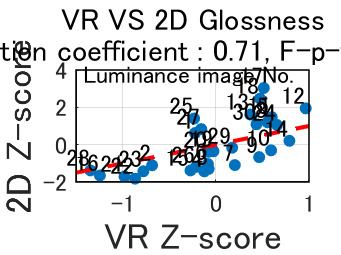

%-----------------------------------
% Exp3 vs Old all coef
%-----------------------------------
% fp-value (0.05以下で母集団の分散値に有意差あり)
[~,All_F_p_value,~,~] = vartest2(Exp3H,InoueH);

amp = 1.5;

%散布図
figure;
x = Exp3H(:);
y = InoueH(:);
r = corrcoef(x,y);
r_value = r(1,2);
p = polyfit(x,y,1);
p_fit = polyval(p,x);

scatter(x,y,'filled');
hold on;
%plot(x,p_fit,'r-','LineWidth',1.5);

xlim([-1.5 1.0]);
x_limits = xlim;
%ylim([-1.2 1.2]);
y_limits = ylim;
common_limits = [min([x_limits, y_limits]), max([x_limits, y_limits])];
plot(common_limits, common_limits, 'r--', 'LineWidth', 2);
% グラフ囲む
rectangle('Position', [x_limits(1), y_limits(1), diff(x_limits), diff(y_limits)], ...
          'EdgeColor', 'k', 'LineWidth', 0.75);
% HDR No
for point = 1:length(x)
    text(x(point)-0.01, y(point)+0.01, num2str(HDRNames3(point)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right','FontSize',8*amp);
end
hold off;

text(x_limits(1)*0.95,y_limits(2)*0.95, 'Luminance image No.', 'FontSize', 8*amp);
set(gca,'FontSize',8*amp);
xlabel('VR Z-score','FontSize',12*amp);
ylabel('2D Z-score','FontSize',12*amp);
%title(sprintf('VR VS 2D Glossness\n correlation coefficient : %.2f,Slope : %.2f', r_value,p(1)));
title(sprintf('VR VS 2D Glossness\n correlation coefficient : %.2f, F-p-value : %.2f', r_value,All_F_p_value),'FontSize',10*amp);
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coef.jpg');
saveas(gcf, plotname);



%{
%histgram2
bar1 = Exp3H(:);
err1 = err_Exp3H(:);
bar2 = InoueH(:);

figure;
bar_width = 0.35;
x = 1:length(HDRNames);

hold on;
bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
%errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
hold off;

ylim([-1.2 1.2]);
set(gca, 'XTick', x);
xticklabels(HDRNames3);
xtickangle(90);
set(gca,'FontSize',6*amp);

xlabel('HDR','FontSize',12*amp); 
ylabel('Normalized z-score','FontSize',12*amp);
title(sprintf('HDR: Coef = %.2f,Slope = %.2f', r_value,p(1)),'FontSize',12*amp);
legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
legend('boxoff');
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Hist.jpg');
saveas(gcf, plotname);
%}

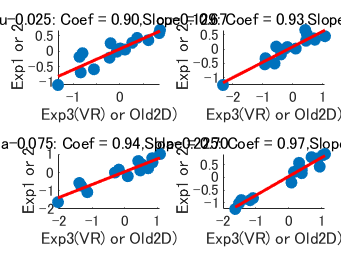

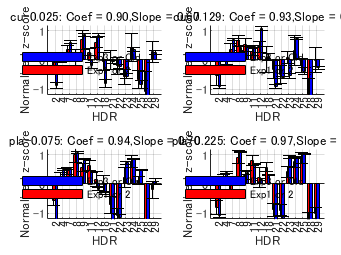

%-----------------------------------
% exp1,exp2 VS VR HDR,material
%-----------------------------------
name1 = 'Exp1';
name2 = 'Exp2';
name3 = 'Exp3';
title = 'Exp2vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp2ThHM15,err_Exp2ThHM15,title,name3,name2);

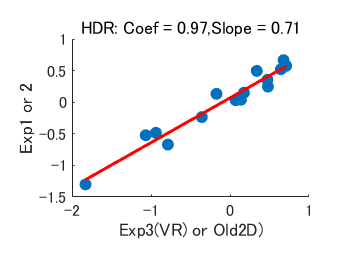

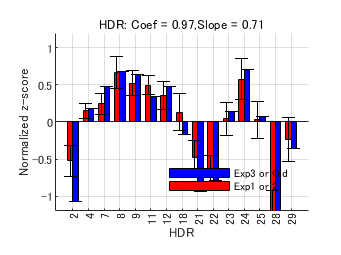

title = 'Exp2vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp2ThH15,err_Exp2ThH15,title,name3,name2);

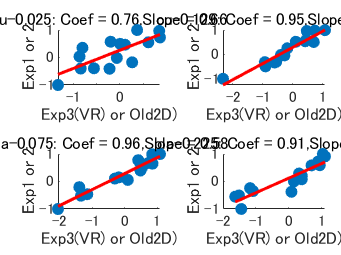

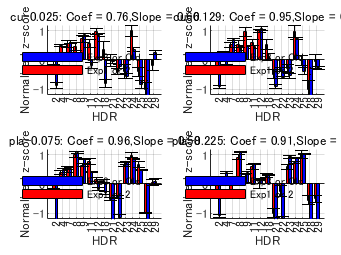

title = 'Exp1vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp1ThHM15,err_Exp1ThHM15,title,name3,name1);

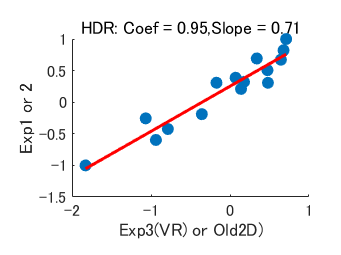

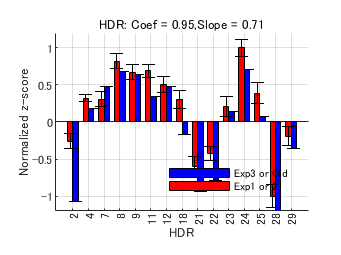

title = 'Exp1vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp1ThH15,err_Exp1ThH15,title,name3,name1);

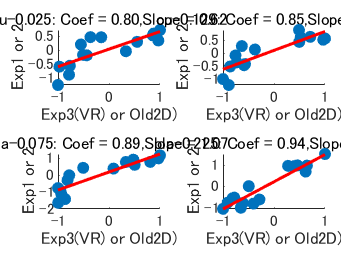

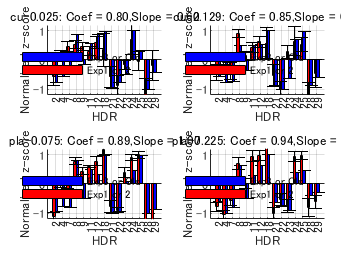

%-----------------------------------
% exp1,exp2 VS Old HDR,material
%-----------------------------------
name1 = 'Exp1';
name2 = 'Exp2';
name3 = 'Old';
errorinoue1 = zeros(size(InoueHM15));
errorinoue2 = zeros(size(InoueH15));

title = 'Exp2vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp2MiHM15,err_Exp2MiHM15,title,name3,name2);

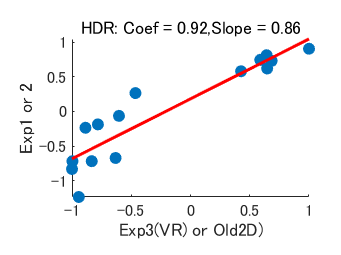

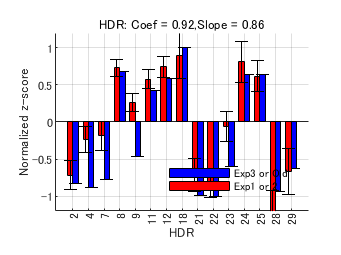

title = 'Exp2vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp2MiH15,err_Exp2MiH15,title,name3,name2);

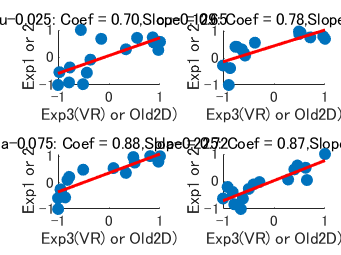

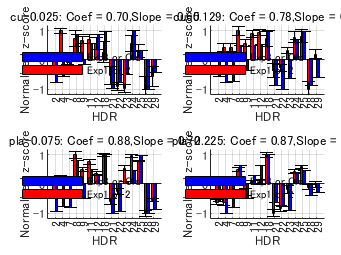

title = 'Exp1vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp1MiHM15,err_Exp1MiHM15,title,name3,name1);

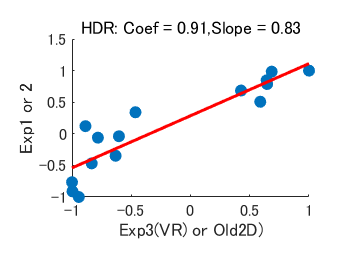

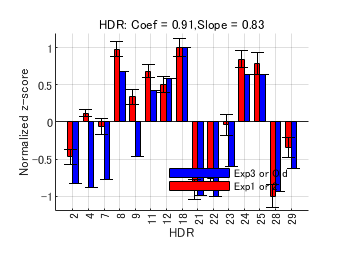

title = 'Exp1vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp1MiH15,err_Exp1MiH15,title,name3,name1);

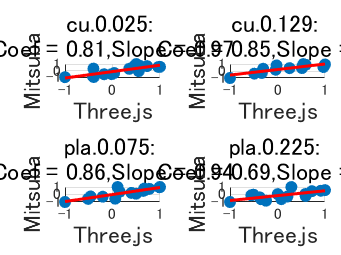

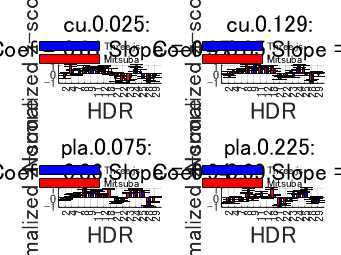

%-----------------------------------
% exp1,2 VS
%-----------------------------------
amp = 1;
%Exp1
title = 'Three.js vs Mitsuba';
xlana = 'Three.js';
ylana = 'Mitsuba';
Make_2dims_vsgraph_Coef_Hist(Exp1ThHM15,err_Exp1ThHM15,Exp1MiHM15,err_Exp1MiHM15,title,xlana,ylana,amp);

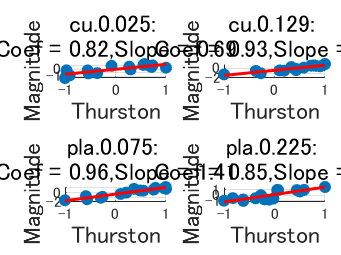

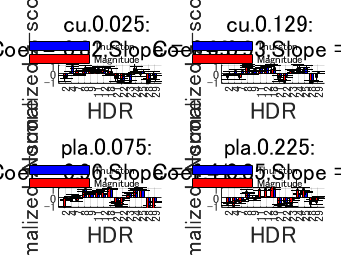


%Exp2
title = 'Thurston vs Magnitude';
xlana = 'Thurston';
ylana = 'Magnitude';
Make_2dims_vsgraph_Coef_Hist(Exp1MiHM15,err_Exp1MiHM15,Exp2MiHM15,err_Exp2MiHM15,title,xlana,ylana,amp);

%{
%-----------------------------------
% Exp3 Material Shape
%-----------------------------------
for mat = 1:size(Exp3HMS,2)
    figure;
    hold on;
    for shape = 1:size(Exp3HMS,3)
        subplot(2, 3, shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, Exp3HMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, Exp3HMS(:,mat,shape), err_Exp3HMS(:,mat,shape), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' MatNames2{mat} '&' ShapeNames{shape}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Exp3_MS_', MatNames2{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Exp3 Material
%-----------------------------------
figure;
hold on;
for mat = 1:4
    subplot(2, 2, mat);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HM(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HM(:,mat), error_Exp3HMSNorm(:,mat), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
end
plotname = strcat(ana_result, '/Exp3_Material', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(Exp3HS,2)
    subplot(2,3,shape);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HS(shape, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HS(shape, :), error_Exp3HSNorm(shape,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' ShapeNames{shape}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

end
plotname = strcat(ana_result, '/Exp3_', 'Shape','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 HDR
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb = bar(x + bar_width/2, Exp3H, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, Exp3H, error_Exp3HNorm, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Normalized z-score', 'FontSize', 16);
title('HDR', 'FontSize', 16);
plotname = strcat(ana_result, '/Exp3_HDR.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material
%-----------------------------------
figure;
hold on;
for mat = 1:size(InoueHM,2)
    subplot(2,2,mat);
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueMHNorm(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueMHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueMatname{mat}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Material','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(InoueHS,2)
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueSHNorm(:,shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueSHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Normalized z-score', 'FontSize', 16);
    title(['compare of ' InoueShapeName{shape}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Shape', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material shape
%-----------------------------------
for mat = 1:size(InoueHMS,2)
    figure;
    hold on;
    for shape = 1:size(InoueHMS,3)
        subplot(2,3,shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, InoueHMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        %errorbar(x + bar_width/2, InoueMHSNorm(:,matnum, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' InoueMatname{mat} '&' InoueShapeName{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Old_MS_', InoueMatname{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end
%}